Step 1. Verify the image


OriginalImagePath = "verifytest.jpg";
%Verify that the image is an ok Size. This is mostly done to evade long
%running time since the program can handle almost any size
ImageToUse = verifyImage("verifytest.jpg");

row = 20

col = 10

colors = 3

Image is smaller than 100px, scaling performed. consider using larger picture


Step 2. Choose your options


%%choose the size of the tiles that divedes the original image into
%%sections
%%larger values may give a bad result and smaller values my affect the
%%performance of structural similarity
TileSize = 5;

%%choose how many images you want in the imageDataBase
DbSize= 100;

Reproduce with regards to structural simularity and reduced database according to Kmeans

%%Create array from folder containing ImageDatabase, the folder needs to
%%contain file of the format jpg.
myCellArray = createCellArrayFromDir("Images/flower"); 

now reading Images\flower\flower_0000.jpg
now reading Images\flower\flower_0001.jpg
now reading Images\flower\flower_0002.jpg
now reading Images\flower\flower_0003.jpg
now reading Images\flower\flower_0004.jpg
now reading Images\flower\flower_0005.jpg
now reading Images\flower\flower_0006.jpg
now reading Images\flower\flower_0007.jpg
now reading Images\flower\flower_0008.jpg
now reading Images\flower\flower_0009.jpg
now reading Images\flower\flower_0010.jpg
now reading Images\flower\flower_0011.jpg
now reading Images\flower\flower_0012.jpg
now reading Images\flower\flower_0013.jpg
now reading Images\flower\flower_0014.jpg
now reading Images\flower\flower_0015.jpg
now reading Images\flower\flower_0016.jpg
now reading Images\flower\flower_0017.jpg
now reading Images\flower\flower_0018.jpg
now reading Images\flower\flower_0019.jpg
now reading Images\flower\flower_0020.jpg
now reading Images\flower\flower_0021.jpg
now reading Images\flower\flower_0022.jpg
now reading Images\flower\flower_0

inpict = 200×100×3 uint8 array
inpict(:,:,1) =

   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203
   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   

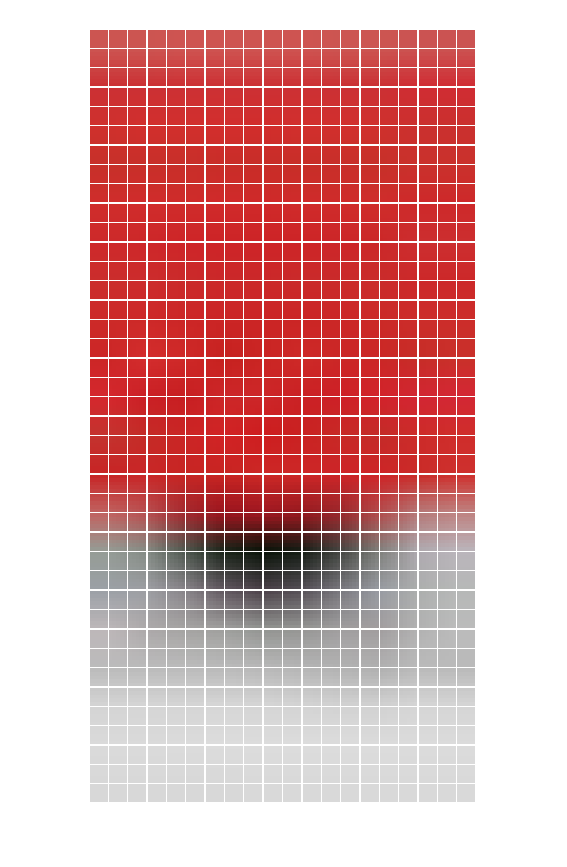

outputArg1 = 40×20 string array
    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"
    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flo

%%Reduces Array from elements in directory to 100 using K-means must be
%%atleast 100 elements in the array
kmeanedArray = KmeansOnCellArray(myCellArray,DbSize);



%%converts image to namearray consisting of reduced database
%%choose either ssim or not

%%using just tiles
%%nameArray= NamearrayUsingTiles(ImageToUse,kmeanedArray,5);

%%accounting for structural similarity
nameArray= reconstructWithSsim(ImageToUse,kmeanedArray,5);


%%regular reproduction
result = reconstructFromNameArray(nameArray,1);

Reproduce, areas with same images merges to lagerger images

%%Create array from folder containing ImageDatabase, the folder needs to
%%contain file of the format jpg.
myCellArray = createCellArrayFromDir("Images/flower"); 

now reading Images\flower\flower_0000.jpg
now reading Images\flower\flower_0001.jpg
now reading Images\flower\flower_0002.jpg
now reading Images\flower\flower_0003.jpg
now reading Images\flower\flower_0004.jpg
now reading Images\flower\flower_0005.jpg
now reading Images\flower\flower_0006.jpg
now reading Images\flower\flower_0007.jpg
now reading Images\flower\flower_0008.jpg
now reading Images\flower\flower_0009.jpg
now reading Images\flower\flower_0010.jpg
now reading Images\flower\flower_0011.jpg
now reading Images\flower\flower_0012.jpg
now reading Images\flower\flower_0013.jpg
now reading Images\flower\flower_0014.jpg
now reading Images\flower\flower_0015.jpg
now reading Images\flower\flower_0016.jpg
now reading Images\flower\flower_0017.jpg
now reading Images\flower\flower_0018.jpg
now reading Images\flower\flower_0019.jpg
now reading Images\flower\flower_0020.jpg
now reading Images\flower\flower_0021.jpg
now reading Images\flower\flower_0022.jpg
now reading Images\flower\flower_0

inpict = 200×100×3 uint8 array
inpict(:,:,1) =

   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203
   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   

outputArg1 = 40×20 string array
    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"
    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flower_0003.jpg"    "Images\flower\flo

%%Reduces Array from elements in directory to 100 using K-means must be
%%atleast 100 elements in the array
kmeanedArray = KmeansOnCellArray(myCellArray,DbSize);



%%converts image to namearray consisting of reduced database
%%choose either ssim or not

%%using just tiles
%%nameArray= NamearrayUsingTiles(ImageToUse,kmeanedArray,5);

%%accounting for structural similarity
nameArray= reconstructWithSsim(ImageToUse,kmeanedArray,5);



%%areas containing same images is replaced with larger images
result = reconstructFromNameArrayDifferentSizes(nameArray);

result = result(:,:,1) =

    0.8274    0.8274    0.8274    0.8274    0.8275    0.8276    0.8278    0.8280    0.8281    0.8281    0.8281    0.8279    0.8274    0.8267    0.8259    0.8251    0.8244    0.8238    0.8235    0.8236    0.8240    0.8245    0.8252    0.8260    0.8268    0.8275    0.8281    0.8285    0.8289    0.8292    0.8296    0.8301    0.8308    0.8316    0.8327    0.8341    0.8358    0.8375    0.8393    0.8410    0.8426    0.8439    0.8451    0.8462    0.8473    0.8482    0.8492    0.8502    0.8512    0.8524    0.8539    0.8555    0.8571    0.8584    0.8594    0.8599    0.8596    0.8582    0.8559    0.8530    0.8500    0.8473    0.8454    0.8446    0.8452    0.8469    0.8496    0.8527    0.8561    0.8595    0.8624    0.8647    0.8667    0.8687    0.8705    0.8722    0.8735    0.8746    0.8754    0.8756    0.8754    0.8748    0.8740    0.8730    0.8720    0.8711    0.8704    0.8698    0.8692    0.8686    0.8681    0.8675    0.8669    0.8663    0.8658    0.8652    0.8647    

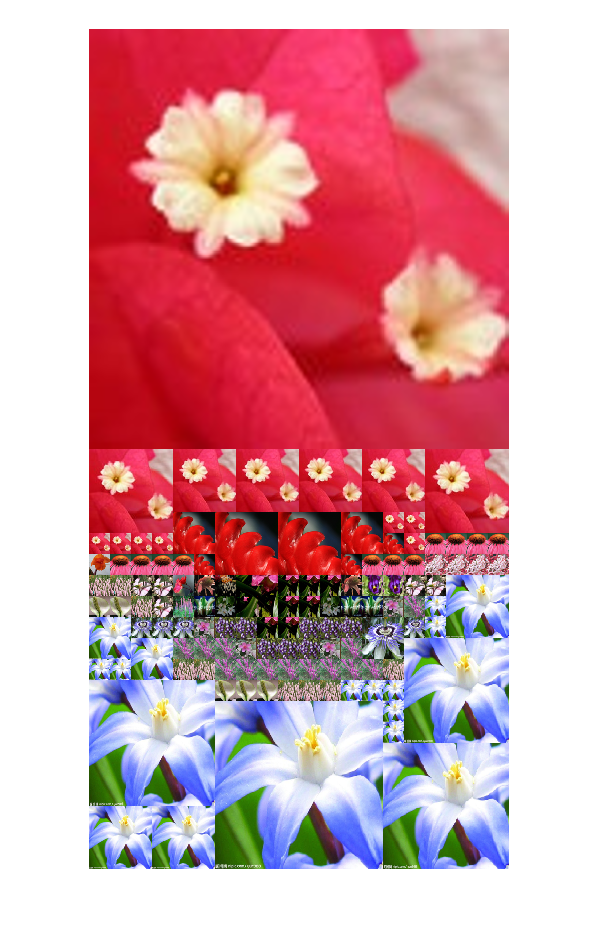


imshow(result)

From this stage you can test reduction of database depending on image to reproduce

**Do not run unless u want tro try another folder**

folder = "Images/flower"; % locate folder
name = 'labValuesFlowers.mat';
calculateLabValues(folder, name);

100%
All Lab values has been stored
Elapsed time is 33.629616 seconds.


clear all;
% Estimated run time: 1 minute.

Select an image to reproduce and reproduce it!

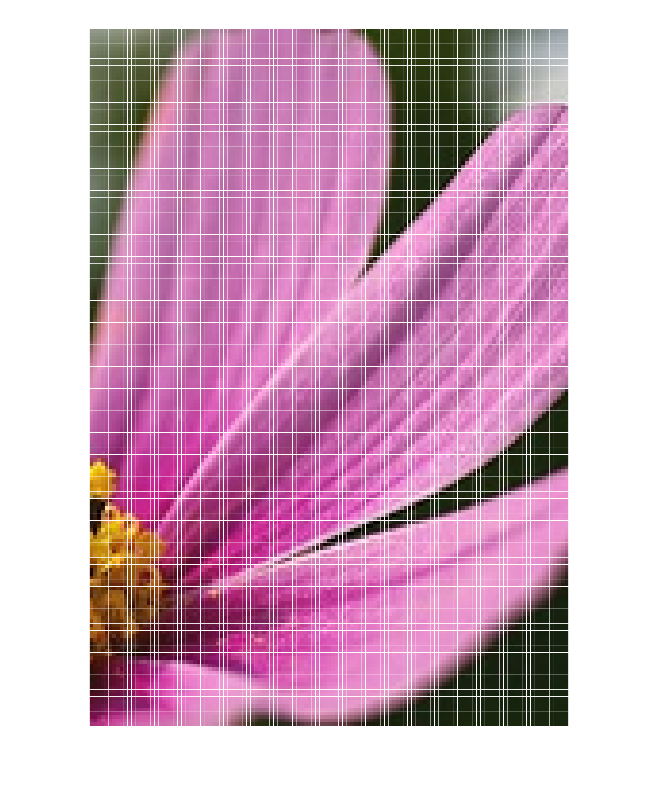

Elapsed time is 73.261357 seconds.


I = imread('Images/flower/flower_0066.jpg');
name = 'reproduced_flower_0066.jpg';
numberOfColors = 10;
imagesPerColor = 1;
reproducedImage = reproduceImage(I,name, numberOfColors, imagesPerColor);


% Estimated run time: 194 seconds

imageSize = size(reproducedImage);
I = im2double(I);
I = imresize(I, [imageSize(1) imageSize(2)], 'bicubic');


Quality meassures if you're interested :) 

[SCIELAB,SSIM,SNR] = qualityMeasure(I,reproducedImage)

I = imread('Images/flower/flower_0066.jpg');
I = im2double(I);
imageSize = size(I);
reproducedImage2 = reproducedImage;
reproducedImage2 = imresize(reproducedImage2, [imageSize(1) imageSize(2)], 'bicubic');
[SCIELAB,SSIM,SNR] = qualityMeasure(I,reproducedImage2)

figure;
imshow(reproducedImage2)

I = imread('Images/flower/flower_0066.jpg');
I = im2double(I);
imageSize = size(I);
reproducedImage2 = reproducedImage;
reproducedImage2 = imresize(reproducedImage2, [imageSize(1) imageSize(2)], 'bilinear');
[SCIELAB,SSIM,SNR] = qualityMeasure(I,reproducedImage2)

figure;
imshow(reproducedImage2)
